## Anomaly Detection and Recommender Systems

## 1. Anomaly Detection

In this exercise, we will implement an anomaly detection algorithm to detect anomalous behavior in server computers. The features measure the throughput (mb/s) and latency (ms) of response of each server. While our servers oure operating, we collected $m = 307$ examples of how they oure behaving, and thus have an unlabeled dataset $\{x^{(1)},\ldots,x^{(m)}\}
$. we suspect that the vast majority of these examples are 'normal' (non-anomalous) examples of the servers operating normally, but there might also be some examples of servers acting anomalously within this dataset.

  We will use a Gaussian model to detect anomalous examples in our dataset. we will first start on a 2D dataset that will allow we to visualize what the algorithm is doing. On that dataset we will fit a Gaussian distribution and then find values that have very low probability and hence can be considered anomalies. After that, we will apply the anomaly detection algorithm to a larger dataset with many dimensions.

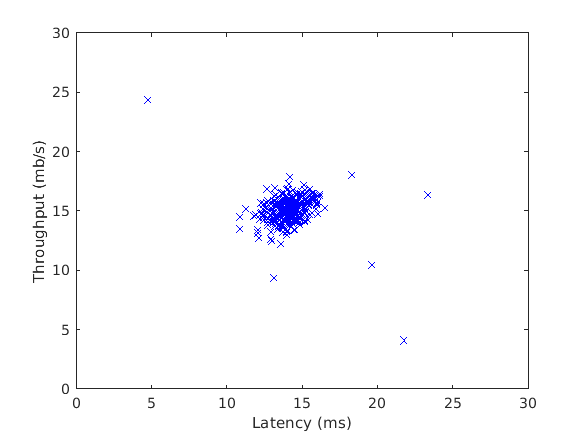

% The following command loads the dataset. we should now have the variables X, Xval, yval in our environment
load('ex8data1.mat');

% Visualize the example dataset
plot(X(:, 1), X(:, 2), 'bx');
axis([0 30 0 30]);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');

### 1.1 Gaussian distribution

To perform anomaly detection, we will first need to fit a model to the data's distribution. Given a training set $\{x^{(1)},\dots,x^{(m)}\}$ (where $x^{(i)}\in\mathbb{R}^n$), we want to estimate the Gaussian distribution for each of the features $x_i$. For each feature $i = 1\ldots n$ we need to find parameters $\mu_i$ and $\sigma^2_i$ that fit the data in the $i$-th dimension $\{x_i^{(1)},\ldots,x^{(m)}_i\}$(the $i$-th dimension of each example).

    The Gaussian distribution is given by


$$p(x;\mu,\sigma^2)=\frac{1}{\sqrt{2\pi\sigma^2}}e^{-\frac{(x-\mu)^2}{2\sigma^2}}$$


where $\mu$ is the mean and $\sigma^2$ controls the variance.

### 1.2 Estimating parameters for a Gaussian

we can estimate the parameters, $(\mu_i,\sigma_i^2)$, of the $i$-th feature by using the following equations. To estimate the mean, we will use:

$\mu_i = \frac{1}{m}\sum_{j=1}^m{x^{(j)}}$,

and for the variance we will use:

$\sigma^2_i = \frac{1}{m}\sum_{j=1}^m{(x^{(j)}-\mu_j)^2}$.

 We can see that most of the examples are in the region with the highest probability, while the anomalous examples are in the regions with loour probabilities.

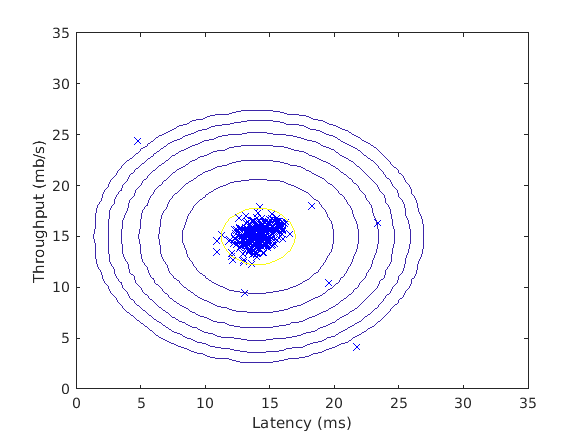

%  Estimate mu and sigma2
[mu, sigma2] = estimateGaussian(X);

%  Returns the density of the multivariate normal at each data point (row) of X
p = multivariateGaussian(X, mu, sigma2);

%  Visualize the fit
visualizeFit(X,  mu, sigma2);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');

### 1.3 Selecting the threshold, $\epsilon$

Now that we have estimated the Gaussian parameters, we can investigate which examples have a very high probability given this distribution and which examples have a very low probability. The low probability examples are more likely to be the anomalies in our dataset. One way to determine which examples are anomalies is to select a threshold based on a cross validation set. In this part of the exercise, we will implement an algorithm to select the threshold $\epsilon$ using the $F_1$ score on a cross validation set.

  We should now complete the code in `selectThreshold.m`. For this, we will use a cross validation set $\{(x^{(1)}_{cv},y^{(1)}_{cv}),\ldots, (x^{(m)}_{cv},y^{(m)}_{cv})\}$, where the label $y = 1$ corresponds to an anomalous example, and $y = 0$ corresponds to a normal example. For each cross validation example, we will compute $p(x^{(i)}_{cv})$. The vector of all of these probabilities $p(x^{(1)}_{cv}),\ldots,p(x^{(m)}_{cv})$ is passed to `selectThreshold.m` in the vector `pval`. The corresponding labels $y^{(1)}_{cv},\ldots,y^{m)}_{cv}$ is passed to the same function in the vector `yval`.

    The $F_1$ score is computed using precision (*prec*) and recall (*rec*):

$F_1 = \frac{2 ( prec)(rec)}{prec + rec}$,

we compute precision and recall by:


$$prec = \frac{tp}{tp + fp}$$



$$rec = \frac{tp}{tp + fn}$$


where

- $tp$ is the number of true positives: the ground truth label says it's an anomaly and our algorithm correctly classified it as an anomaly.

- $fp$ is the number of false positives: the ground truth label says it's not an anomaly, but our algorithm incorrectly classified it as an anomaly.

- $fn$ is the number of false negatives: the ground truth label says it's an anomaly, but our algorithm incorrectly classified it as not being anomalous.

pval = multivariateGaussian(Xval, mu, sigma2);

[epsilon, F1] = selectThreshold(yval, pval);
fprintf('Best epsilon found using cross-validation: %e\n', epsilon);

Best epsilon found using cross-validation: 8.990853e-05


fprintf('Best F1 on Cross Validation Set:  %f\n', F1);

Best F1 on Cross Validation Set:  0.875000


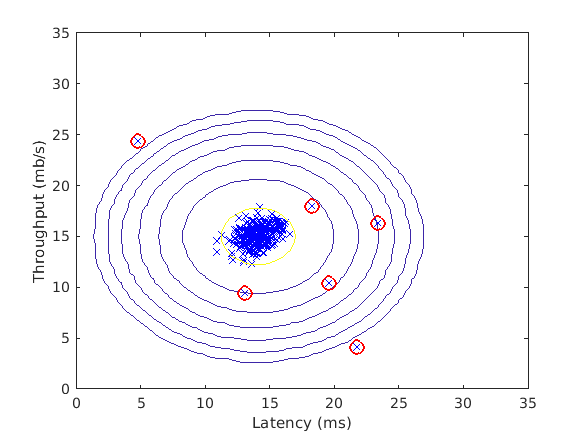


%  Find the outliers in the training set and plot the
outliers = find(p < epsilon);

%  Visualize the fit
visualizeFit(X,  mu, sigma2);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');
%  Draw a red circle around those outliers
hold on
plot(X(outliers, 1), X(outliers, 2), 'ro', 'LineWidth', 2, 'MarkerSize', 10);
hold off

### 1.4 High dimensional dataset

%  Loads the second dataset. we should now have the variables X, Xval, yval in our environment
load('ex8data2.mat');

%  Apply the same steps to the larger dataset
[mu, sigma2] = estimateGaussian(X);

%  Training set 
p = multivariateGaussian(X, mu, sigma2);

%  Cross-validation set
pval = multivariateGaussian(Xval, mu, sigma2);

%  Find the best threshold
[epsilon, F1] = selectThreshold(yval, pval);
fprintf('Best epsilon found using cross-validation: %e\n', epsilon);
fprintf('Best F1 on Cross Validation Set:  %f\n', F1);

Best epsilon found using cross-validation: 1.377229e-18


fprintf('# Outliers found: %d\n', sum(p < epsilon));

Best F1 on Cross Validation Set:  0.615385


# Outliers found: 117


## 2. Recommender Systems

In this part of the exercise, we will implement the collaborative filtering learning algorithm and apply it to a dataset of movie ratings*. This dataset consists of ratings on a scale of 1 to 5. The dataset has $n_u = 943$ users, and $n_m = 1682$ movies. 

*[MovieLens 100k Dataset](https://grouplens.org/datasets/movielens/) from GroupLens Research.

### 2.1 Movie ratings dataset

The code in this section will load the dataset `ex8_movies.mat`, providing the variables `Y` and `R` in our MATLAB environment. The matrix `Y` (a `num_movies` $\times$ `num_users` matrix) stores the ratings $y^{(i,j)}$ (from 1 to 5). The matrix `R` is an binary-valued indicator matrix, where` R(i,j) = 1` if user `j` gave a rating to movie `i`, and `R(i,j) = 0` otherwise. The objective of collaborative filtering is to predict movie ratings for the movies that users have not yet rated, that is, the entries with `R(i,j) = 0`. This will allow us to recommend the movies with the highest predicted ratings to the user.

    To help we understand the matrix `Y`, the code below will compute the average movie rating for the first movie (Toy Story) and output the average rating to the screen. Throughout this part of the exercise, we will also be working with the matrices, `X` and `Theta`:

`X = `$\left\lbrack \begin{array}{c}
-{\;\left(x^{\left(1\right)} \right)}^T -\\
-{\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\;\left(x^{\left(n_m \right)} \right)}^T -
\end{array}\right\rbrack$,    `Theta = `$\left\lbrack \begin{array}{c}
-{\;\left(\theta^{\left(1\right)} \right)}^T -\\
-{\;\left(\theta^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\;\left(\theta^{\left(n_u \right)} \right)}^T -
\end{array}\right\rbrack$.

% Load data
load('ex8_movies.mat');

- `Y` is a 1682 x 943 matrix, containing ratings (1 - 5) of 1682 movies on 943 users

- `R` is a 1682 x 943 matrix, where `R(i,j)` = 1 if and only if user `j` gave a rating to movie `i`

% From the matrix, we can compute statistics like average rating.
fprintf('Average rating for movie 1 (Toy Story): %f / 5\n\n', mean(Y(1, R(1, :))));
%  we can "visualize" the ratings matrix by plotting it with imagesc

Average rating for movie 1 (Toy Story): 3.878319 / 5



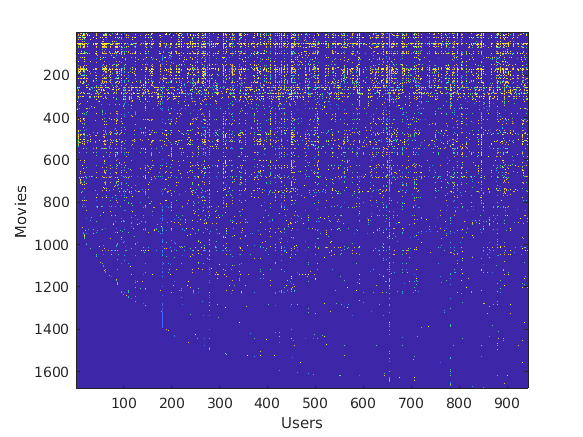

imagesc(Y);
ylabel('Movies');
xlabel('Users');

The $i$-th row of `X` corresponds to the feature vector $x^{(i)}$ for the $i$-th movie, and the $j$-th row of `Theta` corresponds to one parameter vector $\theta^{(j)}$, for the $j$-th user. Both $x^{(i)}$ and $\theta^{(j)}$ are $n$-dimensional vectors. For the purposes of this exercise, we will use $n = 100$, and therefore, $x^{(i)} \in\mathbb{R}^{100}$ and $\theta^{(j)} \in\mathbb{R}^{100}$. Correspondingly, `X` is a $n_m\times 100$ matrix and `Theta` is a $n_u\times 100$ matrix.

### 2.2 Collaborative filtering learning algorithm

Now, we will start implementing the collaborative filtering learning algorithm. we will start by implementing the cost function (without regularization). The collaborative filtering algorithm in the setting of movie recommendations considers a set of $n$-dimensional parameter vectors $x^{(1)},\ldots,x^{(n_m)}$ and $\theta^{(1)},\ldots, \theta^{(n_u)}$, where the model predicts the rating for movie $i$ by user $j$ as $y^{(i,j)} = (\theta^{(j)})^T x^{(i)}$. Given a dataset that consists of a set of ratings produced by some users on some movies, we wish to learn the parameter vectors $x^{(1)},\ldots,x^{(n_m)},\;\theta^{(1)},\ldots,\theta^{(n_u)}$ that produce the best fit (minimizes the squared error).

#### 2.2.1 Collaborative filtering cost function

The collaborative filtering cost function (without regularization) is given by


$$J\left(x^{(i)},\ldots,x^{(n_m)},\;\theta^{(1)},\ldots,\theta^{(n_u)}\right)
=\frac{1}{2}\sum_{(i,j):r(i,j)=1}\left((\theta^{(j)})^Tx^{(i)}-y^{(i,j)}\right)^2$$


%  Load pre-trained weights (X, Theta, num_users, num_movies, num_features)
load('ex8_movieParams.mat');

%  Reduce the data set size so that this runs faster
num_users = 4; num_movies = 5; num_features = 3;
X = X(1:num_movies, 1:num_features);
Theta = Theta(1:num_users, 1:num_features);
Y = Y(1:num_movies, 1:num_users);
R = R(1:num_movies, 1:num_users);

%  Evaluate cost function
J = cofiCostFunc([X(:); Theta(:)],  Y, R, num_users, num_movies,num_features, 0);
fprintf('Cost at loaded parameters: %f ',J);

Cost at loaded parameters: 22.224604 

#### 2.2.2 Collaborative filtering gradient

The gradients of the cost function is given by:


$$\frac{\partial J}{\partial x_k^{(i)}} 
= \sum_{j:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right)\theta_k^{(j)}$$



$$\frac{\partial J}{\partial \theta_k^{(j)}} = \sum_{i:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right) x_k^{(i)}$$


To get started, we can implement the gradient with a `for` loop over movies (for computing $\frac{\partial J}{\partial x_k^{(i)}$) and a `for` loop over users (for computing $\frac{\partial J}{\partial \theta_k^{(j)}$). When we first implement the gradient, we might start with an unvectorized version, by implementing another inner `for` loop that computes each element in the summation. After we have completed the gradient computation this way, we should try to vectorize our implementation (vectorize the inner `for` loops), so that we're left with only two `for` loops (one for looping over movies to compute $\frac{\partial J}{\partial x_k^{(i)}$ for each movie, and one for looping over users to compute $\frac{\partial J}{\partial \theta_k^{(j)}$ for each user).

    To perform the vectorization, we might find this helpful: we should come up with a way to compute all the derivatives associated with $x^{(i)}_1,x^{(i)}_2,\ldots,x^{(i)}_n$, (i.e., the derivative terms associated with the feature vector $x^{(i)}$) at the same time. Let us define the derivatives for the feature vector of the $i$-th movie as:


$${\left({\mathrm{X}}_{\textrm{grad}} \left(\mathrm{i},:\right)\right)}^T =\left\lbrack \begin{array}{c}
\frac{\partial J}{\partial x_1^{\left(i\right)} }\\
\frac{\partial J}{\partial x_2^{\left(i\right)} }\\
\vdots \\
\frac{\partial J}{\partial x_n^{\left(i\right)} }
\end{array}\right\rbrack =\sum_{j:r\left(i,j\right)=1} \left({\left(\theta^{\left(j\right)} \right)}^T x^{\left(i\right)} -y^{\left(i,j\right)} \right)\;\theta^{\left(j\right)}$$


To vectorize the above expression, we can start by indexing into `Theta` and `Y` to select only the elements of interest (that is, those with $r(i,j) = 1$). Intuitively, when we consider the features for the $i$-th movie, we only need to be concerned about the users who had given ratings to the movie, and this allows we to remove all the other users from `Theta` and `Y`.

${\mathrm{X}}_{\mathrm{grad}} \left(i,:\right)=\left(\mathrm{X}\left(i,:\right)*{\mathrm{Theta}}_{\mathrm{temp}}^T -{\mathrm{Y}}_{\mathrm{temp}} \right)*{\mathrm{Theta}}_{\mathrm{temp}}$.

%  Check gradients by running checkNNGradients
checkCostFunction;

    0.8700    0.8700
         0         0
    2.0479    2.0479
   -2.7341   -2.7341
    2.3462    2.3462
         0         0
   -3.1380   -3.1380
    4.7809    4.7809
    1.9846    1.9846
         0         0
    1.2999    1.2999
   -0.9485   -0.9485
    0.4700    0.4700
   -0.2653   -0.2653
    4.1396    4.1396
   -0.7753   -0.7753
   -0.9104   -0.9104
   -0.9614   -0.9614
    0.6241    0.6241
   -5.6192   -5.6192
    0.8609    0.8609
    0.6332    0.6332
   -0.5509   -0.5509
   -0.3591   -0.3591
    0.6803    0.6803
   -0.6341   -0.6341
   -0.5817   -0.5817

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your cost function implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 1.21911e-12


#### 2.2.3 Regularized cost function

The cost function for collaborative filtering with regularization is given by


$$J\left(x^{(i)},\ldots,x^{(n_m)},\;\theta^{(1)},\ldots,\theta^{(n_u)}\right)
=\frac{1}{2}\sum_{(i,j):r(i,j)=1}\left((\theta^{(j)})^Tx^{(i)}-y^{(i,j)}\right)^2
+\left(\frac{\lambda}{2}\sum_{j=1}^{n_u}{\sum_{k=1}^{n}{(\theta_k^{(j)})^2}}\right)
+\left(\frac{\lambda}{2}\sum_{i=1}^{n_m}{\sum_{k=1}^{n}{(x_k^{(i)})^2}}\right)$$


%  Evaluate cost function
J = cofiCostFunc([X(:); Theta(:)], Y, R, num_users, num_movies, num_features, 1.5);      
fprintf('Cost at loaded parameters (lambda = 1.5): %f',J);

Cost at loaded parameters (lambda = 1.5): 31.344056

#### 2.2.4 Regularized gradient

Now that we have implemented the regularized cost function, we should proceed to implement regularization for the gradient. we should add to our implementation in `cofiCostFunc.m` to return the regularized gradient by adding the contributions from the regularization terms. Note that the gradients for the regularized cost function is given by:


$$\frac{\partial J}{\partial x_k^{(i)}} 
= \sum_{j:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right)\theta_k^{(j)}+\lambda x_k^{(i)}$$



$$\frac{\partial J}{\partial \theta_k^{(j)}} = \sum_{i:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right) x_k^{(i)}+\lambda\theta_k^{(j)}$$


%  Check gradients by running checkNNGradients
checkCostFunction(1.5);

*we should now submit our solutions.  Enter *`submit`* at the command prompt, then and enter or confirm our login and token when prompted.*

### 2.3 Learning movie recommendations

After we have finished implementing the collaborative ltering cost function and gradient, we can now start training our algorithm to make movie recommendations for ourself. In the code below, we can enter our own movie preferences, so that later when the algorithm runs, we can get our own movie recommendations! we have filled out some values according to our own preferences, but we should change this according to our own tastes. The list of all movies and their number in the dataset can be found listed in the file movie idx.txt.

% Load movvie list
movieList = loadMovieList();

   -0.2471   -0.2471
    1.9414    1.9414
   -1.9787   -1.9787
    0.7006    0.7006
    3.5101    3.5101
    0.2543    0.2543
    1.5416    1.5416
    2.3990    2.3990
   -3.2561   -3.2561
   -4.1617   -4.1617
    4.7051    4.7051
   -1.1998   -1.1998
    0.3539    0.3539
    1.3291    1.3291
    1.2457    1.2457
   -1.5213   -1.5213
    0.5858    0.5858
   -1.5169   -1.5169
    2.1835    2.1835
   -3.5664   -3.5664
    1.4779    1.4779
    1.0621    1.0621
   -1.8107   -1.8107
   -4.9811   -4.9811
   -2.8814   -2.8814
    0.5047    0.5047
   -4.5334   -4.5334

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your cost function implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 2.28773e-12



% Initialize my ratings
my_ratings = zeros(1682, 1);

% Check the file movie_idx.txt for id of each movie in our dataset
% For example, Toy Story (1995) has ID 1, so to rate it "4", we can set
my_ratings(1) = 4;
% Or suppose did not enjoy Silence of the Lambs (1991), we can set
my_ratings(98) = 2; 

% we have selected a few movies we liked / did not like and the ratings we gave are as follows:
my_ratings(7) = 3;
my_ratings(12)= 5;
my_ratings(54) = 4;
my_ratings(64)= 5;
my_ratings(66)= 3;
my_ratings(69) = 5;
my_ratings(183) = 4;
my_ratings(226) = 5;
my_ratings(355)= 5;

fprintf('\n\nNew user ratings:\n');
for i = 1:length(my_ratings)
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), movieList{i});
    end
end



New user ratings:


#### 2.3.1 Recommendations

After the additional ratings have been added to the dataset, the code below will proceed to train the collaborative filtering model. This will learn the parameters `X` and `Theta`. 

%  Load data
load('ex8_movies.mat');

%  Y is a 1682x943 matrix, containing ratings (1-5) of 1682 movies by 943 users
%  R is a 1682x943 matrix, where R(i,j) = 1 if and only if user j gave a rating to movie i

Rated 4 for Toy Story (1995)
Rated 3 for Twelve Monkeys (1995)
Rated 5 for Usual Suspects, The (1995)
Rated 4 for Outbreak (1995)
Rated 5 for Shawshank Redemption, The (1994)
Rated 3 for While You Were Sleeping (1995)
Rated 5 for Forrest Gump (1994)
Rated 2 for Silence of the Lambs, The (1991)
Rated 4 for Alien (1979)
Rated 5 for Die Hard 2 (1990)
Rated 5 for Sphere (1998)


%  Add our own ratings to the data matrix
Y = [my_ratings Y];
R = [(my_ratings ~= 0) R];

%  Normalize Ratings
[Ynorm, Ymean] = normalizeRatings(Y, R);

%  Useful Values
num_users = size(Y, 2);
num_movies = size(Y, 1);
num_features = 10;

% Set Initial Parameters (Theta, X)
X = randn(num_movies, num_features);
Theta = randn(num_users, num_features);
initial_parameters = [X(:); Theta(:)];

% Set options for fmincg
options = optimset('GradObj','on','MaxIter',100);

% Set Regularization
lambda = 10;
theta = fmincg(@(t)(cofiCostFunc(t, Ynorm, R, num_users, num_movies, num_features,lambda)), initial_parameters, options);

% Unfold the returned theta back into U and W
X = reshape(theta(1:num_movies*num_features), num_movies, num_features);
Theta = reshape(theta(num_movies*num_features+1:end), num_users, num_features);


To predict the rating of movie $i$ for user$j$, we need to compute $(\theta^{(j)})^T x^{(i)}$. Note that we might obtain a different set of the predictions due to different random initializations.

p = X * Theta';
my_predictions = p(:,1) + Ymean;

Iteration     1 | Cost: 3.147179e+05
Iteration     2 | Cost: 1.258353e+05
Iteration     3 | Cost: 1.003162e+05
Iteration     4 | Cost: 8.098216e+04
Iteration     5 | Cost: 6.174263e+04
Iteration     6 | Cost: 4.990692e+04
Iteration     7 | Cost: 4.574697e+04
Iteration     8 | Cost: 4.333935e+04
Iteration     9 | Cost: 4.264168e+04
Iteration    10 | Cost: 4.188885e+04
Iteration    11 | Cost: 4.120568e+04
Iteration    12 | Cost: 4.082442e+04
Iteration    13 | Cost: 4.067975e+04
Iteration    14 | Cost: 4.031180e+04
Iteration    15 | Cost: 4.009608e+04
Iteration    16 | Cost: 3.991522e+04
Iteration    17 | Cost: 3.976256e+04
Iteration    18 | Cost: 3.960765e+04
Iteration    19 | Cost: 3.951726e+04
Iteration    20 | Cost: 3.945804e+04
Iteration    21 | Cost: 3.941524e+04
Iteration    22 | Cost: 3.935598e+04
Iteration    23 | Cost: 3.930324e+04
Iteration    24 | Cost: 3.928257e+04
Iteration    25 | Cost: 3.925262e+04
Iteration    26 | Cost: 3.924258e+04
Iteration    27 | Cost: 3.920573e+04
I


movieList = loadMovieList();

[r, ix] = sort(my_predictions,'descend');
for i=1:10
    j = ix(i);
    if i == 1
        fprintf('\nTop recommendations for we:\n');
    end
    fprintf('Predicting rating %.1f for movie %s\n', my_predictions(j), movieList{j});
end
for i = 1:length(my_ratings)
    if i == 1
        fprintf('\n\nOriginal ratings provided:\n');
    end
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), movieList{i});
    end
end


Top recommendations for you:


Predicting rating 5.0 for movie Someone Else's America (1995)
Predicting rating 5.0 for movie Entertaining Angels: The Dorothy Day Story (1996)
Predicting rating 5.0 for movie They Made Me a Criminal (1939)
Predicting rating 5.0 for movie Saint of Fort Washington, The (1993)
Predicting rating 5.0 for movie Prefontaine (1997)
Predicting rating 5.0 for movie Aiqing wansui (1994)
Predicting rating 5.0 for movie Great Day in Harlem, A (1994)
Predicting rating 5.0 for movie Marlene Dietrich: Shadow and Light (1996)
Predicting rating 5.0 for movie Santa with Muscles (1996)
Predicting rating 5.0 for movie Star Kid (1997)




Original ratings provided:


Rated 4 for Toy Story (1995)
Rated 3 for Twelve Monkeys (1995)
Rated 5 for Usual Suspects, The (1995)
Rated 4 for Outbreak (1995)
Rated 5 for Shawshank Redemption, The (1994)
Rated 3 for While You Were Sleeping (1995)
Rated 5 for Forrest Gump (1994)
Rated 2 for Silence of the Lambs, The (1991)
Rated 4 for Alien (1979)
Rated 5 for Die Hard 2 (1990)
Rated 5 for Sphere (1998)
